clear all;close all;clc;

Lets calculate the homogenius transformation matrix from 0 to 4.

Lets start with T01

syms theta1 d1 a1 alpha1

A1 = [cos(theta1) -sin(theta1)*cos(alpha1) sin(theta1)*sin(alpha1) a1*cos(theta1);
   sin(theta1) cos(theta1)*cos(alpha1) -cos(theta1)*sin(alpha1) a1*sin(theta1);
   0 sin(alpha1) cos(alpha1) d1;
   0 0 0 1];

syms theta1_val   
d1_val = 50;         
a1_val = 0;         
alpha1_val = deg2rad(90);   

% Substitute the values into the symbolic matrix
A1_evaluated = subs(A1, {theta1, d1, a1, alpha1}, {theta1_val, d1_val, a1_val, alpha1_val});

% Display the evaluated transformation matrix
disp(A1_evaluated);

$$\left(\begin{array}{cccc} \cos\left(\theta_{1,\mathrm{val}}\right) & 0 & \sin\left(\theta_{1,\mathrm{val}}\right) & 0\\ \sin\left(\theta_{1,\mathrm{val}}\right) & 0 & -\cos\left(\theta_{1,\mathrm{val}}\right) & 0\\ 0 & 1 & 0 & 50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12

syms theta2 d2 a2 alpha2

A2 = [cos(theta2) -sin(theta2)*cos(alpha2) sin(theta2)*sin(alpha2) a2*cos(theta2);
   sin(theta2) cos(theta2)*cos(alpha2) -cos(theta2)*sin(alpha2) a2*sin(theta2);
   0 sin(alpha2) cos(alpha2) d2;
   0 0 0 1];

syms theta2_val   
d2_val = 0;          % Example: 5 units
a2_val = 93;         % Example: 10 units
alpha2_val = 0;   % Example: 30 degrees (in radians)

% Substitute the values into the symbolic matrix
A2_evaluated = subs(A2, {theta2, d2, a2, alpha2}, {theta2_val, d2_val, a2_val, alpha2_val});

% Display the evaluated transformation matrix
disp(A2_evaluated);

$$\left(\begin{array}{cccc} \cos\left(\theta_{2,\mathrm{val}}\right) & -\sin\left(\theta_{2,\mathrm{val}}\right) & 0 & 93\,\cos\left(\theta_{2,\mathrm{val}}\right)\\ \sin\left(\theta_{2,\mathrm{val}}\right) & \cos\left(\theta_{2,\mathrm{val}}\right) & 0 & 93\,\sin\left(\theta_{2,\mathrm{val}}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23

syms theta3 d3 a3 alpha3

A3 = [cos(theta3) -sin(theta3)*cos(alpha3) sin(theta3)*sin(alpha3) a3*cos(theta3);
   sin(theta3) cos(theta3)*cos(alpha3) -cos(theta3)*sin(alpha3) a3*sin(theta3);
   0 sin(alpha3) cos(alpha3) d3;
   0 0 0 1];

syms theta3_val
d3_val = 0;           % Example: 5 units
a3_val = 93;         % Example: 10 units
alpha3_val = 0;   % Example: 90 degrees (in radians)

% Substitute the values into the symbolic matrix
A3_evaluated = subs(A3, {theta3, d3, a3, alpha3}, {theta3_val, d3_val, a3_val, alpha3_val});

% Display the evaluated transformation matrix
disp(A3_evaluated);

$$\left(\begin{array}{cccc} \cos\left(\theta_{3,\mathrm{val}}\right) & -\sin\left(\theta_{3,\mathrm{val}}\right) & 0 & 93\,\cos\left(\theta_{3,\mathrm{val}}\right)\\ \sin\left(\theta_{3,\mathrm{val}}\right) & \cos\left(\theta_{3,\mathrm{val}}\right) & 0 & 93\,\sin\left(\theta_{3,\mathrm{val}}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34

syms theta4 d4 a4 alpha4

A4 = [cos(theta4) -sin(theta4)*cos(alpha4) sin(theta4)*sin(alpha4) a4*cos(theta4);
   sin(theta4) cos(theta4)*cos(alpha4) -cos(theta4)*sin(alpha4) a4*sin(theta4);
   0 sin(alpha4) cos(alpha4) d4;
   0 0 0 1];

syms theta4_val   
d4_val = 0;          % Example: 5 units
a4_val = 50;            % Example: 10 units
alpha4_val = 0;   % Example: 90 degrees (in radians)

% Substitute the values into the symbolic matrix
A4_evaluated = subs(A4, {theta4, d4, a4, alpha4}, {theta4_val, d4_val, a4_val, alpha4_val});

% Display the evaluated transformation matrix
disp(A4_evaluated);

$$\left(\begin{array}{cccc} \cos\left(\theta_{4,\mathrm{val}}\right) & -\sin\left(\theta_{4,\mathrm{val}}\right) & 0 & 50\,\cos\left(\theta_{4,\mathrm{val}}\right)\\ \sin\left(\theta_{4,\mathrm{val}}\right) & \cos\left(\theta_{4,\mathrm{val}}\right) & 0 & 50\,\sin\left(\theta_{4,\mathrm{val}}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Thus T04 is 

A04 = A1_evaluated*A2_evaluated*A3_evaluated*A4_evaluated;
A04_simp = simplify(A04);
disp(A04_simp)

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{1,\mathrm{val}}\right) & -\sigma_{1}\,\cos\left(\theta_{1,\mathrm{val}}\right) & \sin\left(\theta_{1,\mathrm{val}}\right) & \cos\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\sigma_{1}\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\cos\left(\theta_{1,\mathrm{val}}\right) & \sin\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{2}\\ \sigma_{1} & \sigma_{3} & 0 & 50\,\sigma_{1}+93\,\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+93\,\sin\left(\theta_{2,\mathrm{val}}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}+\theta_{4,\mathrm{val}}\right)\\ \sigma_{2}=50\,\sigma_{3}+93\,\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+93\,\cos\left(\theta_{2,\mathrm{val}}\right)\\ \sigma_{3}=\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}+\theta_{4,\mathrm{val}}\right) \end{array}$$


% Gerum líka frame 5. Gerum fylkið manually
A45 = [1 0 0 -15;
    0 1 0 45;
    0 0 1 0;
    0 0 0 1];
disp(A45);

     1     0     0   -15
     0     1     0    45
     0     0     1     0
     0     0     0     1




%  Homogenius Transformation Matrix er þá
A05 = A04_simp*A45

$$A05 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{1,\mathrm{val}}\right) & -\sigma_{1}\,\cos\left(\theta_{1,\mathrm{val}}\right) & \sin\left(\theta_{1,\mathrm{val}}\right) & \cos\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{2}-15\,\sigma_{3}\,\cos\left(\theta_{1,\mathrm{val}}\right)-45\,\sigma_{1}\,\cos\left(\theta_{1,\mathrm{val}}\right)\\ \sigma_{3}\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\sigma_{1}\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\cos\left(\theta_{1,\mathrm{val}}\right) & \sin\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{2}-15\,\sigma_{3}\,\sin\left(\theta_{1,\mathrm{val}}\right)-45\,\sigma_{1}\,\sin\left(\theta_{1,\mathrm{val}}\right)\\ \sigma_{1} & \sigma_{3} & 0 & 45\,\sigma_{3}+35\,\sigma_{1}+93\,\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+93\,\sin\left(\theta_{2,\mathrm{val}}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}+\theta_{4,\mathrm{val}}\right)\\ \sigma_{2}=50\,\sigma_{3}+93\,\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+93\,\cos\left(\theta_{2,\mathrm{val}}\right)\\ \sigma_{3}=\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}+\theta_{4,\mathrm{val}}\right) \end{array}$$

disp(simplify(A05))

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{1,\mathrm{val}}\right) & -\sigma_{2}\,\cos\left(\theta_{1,\mathrm{val}}\right) & \sin\left(\theta_{1,\mathrm{val}}\right) & \cos\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{1}\\ \sigma_{3}\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\sigma_{2}\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\cos\left(\theta_{1,\mathrm{val}}\right) & \sin\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{1}\\ \sigma_{2} & \sigma_{3} & 0 & 45\,\sigma_{3}+35\,\sigma_{2}+93\,\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+93\,\sin\left(\theta_{2,\mathrm{val}}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=35\,\sigma_{3}-45\,\sigma_{2}+93\,\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+93\,\cos\left(\theta_{2,\mathrm{val}}\right)\\ \sigma_{2}=\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}+\theta_{4,\mathrm{val}}\right)\\ \sigma_{3}=\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}+\theta_{4,\mathrm{val}}\right) \end{array}$$





% Berum saman vð Homogenius transformation

%theta = [0 -0.017 -2.29 2.31]'
theta = [0   -71    -38   -90]'

theta =      0
   -71
   -38
   -90


theta = deg2rad(theta);

A04_float = vpa(simplify(subs(A04_simp, [theta1_val theta2_val theta3_val theta4_val], theta')),3)

$$A04\_float = \left(\begin{array}{cccc} -0.946 & -0.326 & 0 & -47.3\\ 0 & 0 & -1.0 & 0\\ 0.326 & -0.946 & 0 & -110.0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

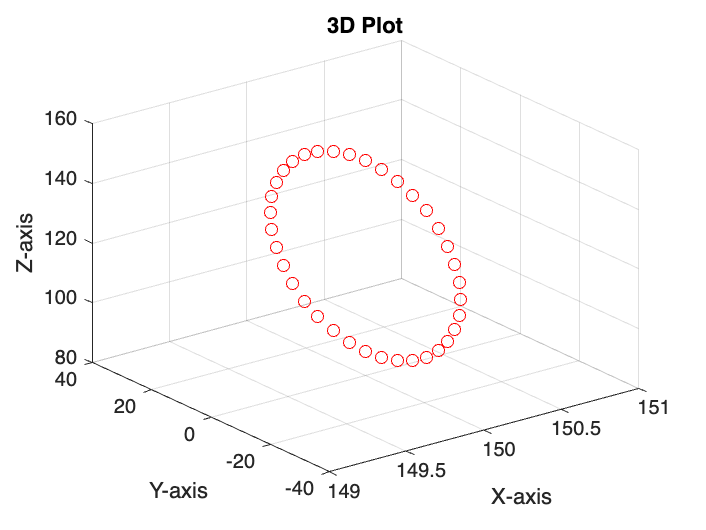

% Notum fallið fyrir inverse kinematics
% gerum hring 

phi = linspace(0, 2*pi, 37); % radians
P0c = [150; 0; 120];         % center point
R = 32;                       % radius
P = P0c + R * [zeros(1, 37); cos(phi); sin(phi)]; % generate points on the circle


% plot(P(2, :), P(3, :), "*")   % plot y vs. z coordinates
% xlabel('y')
% ylabel('z')
% title('Plot of Circle in y-z Plane')

% grid on
% axis equal

figure;
plot3(P(1,:),P(2, :), P(3, :),'ro');  % 'o' specifies points, you can change to '-' for lines
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('3D Plot');
grid on;

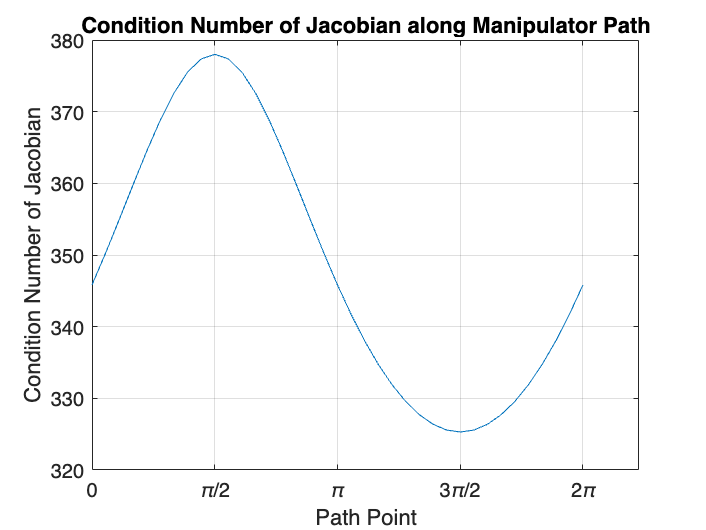



% Setjunm inn í inverse
theta = [theta1 theta2 theta3 theta4]; % Initial angles or placeholder for joint angles

q = zeros(length(P), 4); % Initialize q with the same number of columns as the output of inverse kinematics

for i = 1:length(P)
    q(i, :) = IK(P(1, i), P(2, i), P(3, i), 0); % Store each result as a row in q
end

condition_numbers = zeros(size(q, 1), 1);
for i = 1:size(q, 1)
    % Get the joint configuration for the current point on the path
    joint_config = q(i, :);
    
    % Compute the Jacobian at this configuration (replace with your Jacobian function)
    J = jacobianEE(joint_config);
    
    % Calculate the condition number of the Jacobian
    condition_numbers(i) = cond(J);
end

% Plot the condition number along the path
figure;
plot(phi,condition_numbers);
xlabel('Path Point');
ylabel('Condition Number of Jacobian');
title('Condition Number of Jacobian along Manipulator Path');
grid on;

grid on;

% Customize x-axis with multiples of pi
xticks(0:pi/2:2*pi); % Set x-ticks at intervals of pi/2
xticklabels({'0', '\pi/2', '\pi', '3\pi/2', '2\pi'}); % Set labels

syms q1 q2 q3 q4

    T_ = @(th, d, a, al) [cos(th), -sin(th)*cos(al), sin(th)*sin(al), a*cos(th);
                          sin(th), cos(th)*cos(al), -cos(th)*sin(al), a*sin(th);
                          0, sin(al), cos(al), d;
                          0, 0, 0, 1];
    
    % Define DH parameters based on the given table
    T01 = T_(q1, 50, 0, pi/2);
    T12 = T_(q2, 0, 93, 0);
    T23 = T_(q3, 0, 93, 0);
    T34 = T_(q4, 0, 50, 0);

    % Compute cumulative transformations to frame 4
    T02 = T01 * T12;
    T03 = T02 * T23;
    T04 = T03 * T34;  % Transformation to frame 4 (end effector)
    
    % Additional transformation from frame 4 to frame 5 (camera frame)
    T45 = [1 0 0 -15; 
           0 1 0 45; 
           0 0 1 0; 
           0 0 0 1];
    T05 = T04 * T45; % Transformation to camera frame (frame 5)
    
    % Axes z and Origins o for Jacobian computation
    z0 = [0; 0; 1];
    z1 = T01(1:3, 3);
    z2 = T02(1:3, 3);
    z3 = T03(1:3, 3);

    o0 = [0; 0; 0];
    o1 = T01(1:3, 4);
    o2 = T02(1:3, 4);
    o3 = T03(1:3, 4);
    o4 = T04(1:3, 4); % Position of the end effector
    o5 = T05(1:3, 4); % Position of the camera frame

    % Jacobian columns for the end effector
    J1_ee = [cross(z0, (o4 - o0)); z0];
    J2_ee = [cross(z1, (o4 - o1)); z1];
    J3_ee = [cross(z2, (o4 - o2)); z2];
    J4_ee = [cross(z3, (o4 - o3)); z3];

    % Construct Jacobian matrix for the end effector
    Jee = [J1_ee, J2_ee, J3_ee, J4_ee];
    
    % Jacobian columns for the camera frame
    J1_cam = [cross(z0, (o5 - o0)); z0];
    J2_cam = [cross(z1, (o5 - o1)); z1];
    J3_cam = [cross(z2, (o5 - o2)); z2];
    J4_cam = [cross(z3, (o5 - o3)); z3];

    % Construct Jacobian matrix for the camera
    Jcam = [J1_cam, J2_cam, J3_cam, J4_cam];

simplify(Jcam)

simplify(Jee)


P0c = [150; 0; 120];         % center point
R = 32;                       % radius

phi1 = 0;
phi2 = pi/2;
phi3 = pi;
phi4 = 3*pi/2;

q1 = qFromPhi(phi1,P0c,R)

q1 =     0.2102    1.4302   -1.6699    0.2397


q2 = qFromPhi(phi2,P0c,R)

q2 =     0.0000    0.8818   -1.0961    1.7852


q3 = qFromPhi(phi3,P0c,R)

q3 =    -0.2102    0.3315         0    2.8101


q4 = qFromPhi(phi4,P0c,R)

q4 =    -0.0000    0.8931   -0.7251    4.5444






[J1EE, J1C] = jacobian(q1)

J1EE =   -32.0000  -68.4595   21.5960   -0.0000
  150.0000  -14.6047    4.6071    0.0000
         0  153.3754  140.3404   50.0000
         0    0.2086    0.2086    0.2086
         0   -0.9780   -0.9780   -0.9780
    1.0000    0.0000    0.0000    0.0000


J1C =   -28.8704 -112.4692  -22.4137  -44.0097
  135.3301  -23.9934   -4.7816   -9.3887
         0  138.3754  125.3404   35.0000
         0    0.2086    0.2086    0.2086
         0   -0.9780   -0.9780   -0.9780
    1.0000    0.0000    0.0000    0.0000


[J2EE, J2C] = jacobian(q2)

J2EE =    -0.0000 -102.0000  -30.2169  -50.0000
  150.0000    0.0000    0.0000   -0.0000
         0  150.0000   90.8715    0.0000
         0    0.0000    0.0000    0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    0.0000    0.0000


J2C =    -0.0000  -87.0000  -15.2169  -35.0000
  105.0000    0.0000    0.0000   -0.0000
         0  105.0000   45.8715  -45.0000
         0    0.0000    0.0000    0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    0.0000    0.0000


[J3EE, J3C] = jacobian(q3)

J3EE =    26.2621  -59.2020  -29.6010   -0.0000
  123.1037   12.6298    6.3149   -0.0000
         0  125.8738   37.9369  -50.0000
         0   -0.2086   -0.2086   -0.2086
         0   -0.9780   -0.9780   -0.9780
    1.0000    0.0000    0.0000    0.0000


J3C =    29.3917  -15.1924   14.4087   44.0097
  137.7736    3.2410   -3.0738   -9.3887
         0  140.8738   52.9369  -35.0000
         0   -0.2086   -0.2086   -0.2086
         0   -0.9780   -0.9780   -0.9780
    1.0000    0.0000    0.0000    0.0000


[JEE, JC] = jacobian(q4)

JEE =     0.0000  -38.0000   34.4503   50.0000
  150.0000    0.0000    0.0000   -0.0000
         0  150.0000   91.6908    0.0000
         0   -0.0000   -0.0000   -0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    0.0000    0.0000


JC =     0.0000  -53.0000   19.4503   35.0000
  195.0000    0.0000    0.0000    0.0000
         0  195.0000  136.6908   45.0000
         0   -0.0000   -0.0000   -0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    0.0000    0.0000


% P5
P0c = [150; 0; 120];         % center point
R = 32;  
phi5 = pi/2;
q5 = qFromPhi(phi5,P0c,R);

[JEE5,J5C] = jacobian(q5);

v_4 = [0; -3; 0; 0; 0; 0];  % No rotation components

% Calculate joint velocities
q_dot5 = pinv(J5C) * v_4

q_dot5 =    -0.0286
   -0.0000
    0.0000
    0.0000


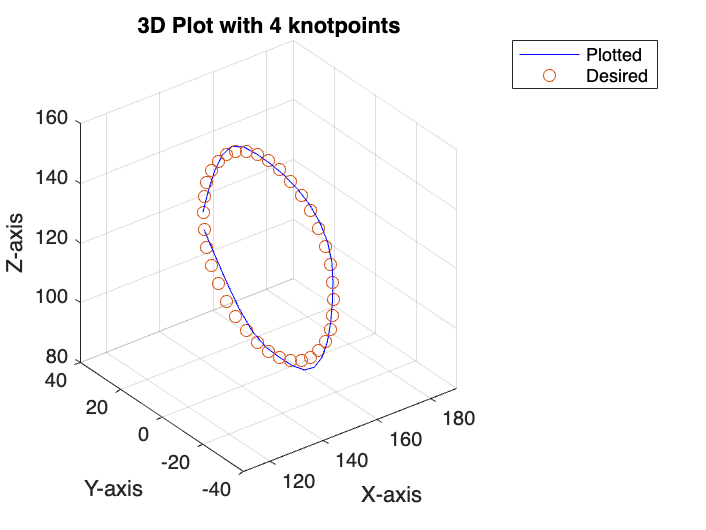

% Part2
% knotpoints
q0 = q(1,:);
q9  = q(9,:);
q18 = q(18,:);
q27 = q(27,:);
q36 = q(36,:);


A = quintic_interpolationV(0,2,q0,[0 0 0]',[0 0 0 0]',q9,[0 -27 0]',[0 0 0 0]');
B = quintic_interpolationV(0,2,q9,[0 -27 0]',[0 0 0 0]',q18,[0 0 -27]',[0 0 0 0]');
C = quintic_interpolationV(0,2,q18,[0 0 -27]',[0 0 0 0]',q27,[0 27 0]',[0 0 0 0]');
D = quintic_interpolationV(0,2,q27,[0 27 0]',[0 0 0 0]',q36,[0 0 0]',[0 0 0 0]');



t = linspace(0,2,9);

segments = {A, B, C, D};
Q = [];
Q_dot = [];
Q_dotdot = [];

for idx = 1:length(segments)
    coeffs = segments{idx};
    Q1 = coeffs(1,6)*t.^5 + coeffs(1,5)*t.^4 + coeffs(1,4)*t.^3 + coeffs(1,3)*t.^2 + coeffs(1,2)*t + coeffs(1,1);
    Q2 = coeffs(2,6)*t.^5 + coeffs(2,5)*t.^4 + coeffs(2,4)*t.^3 + coeffs(2,3)*t.^2 + coeffs(2,2)*t + coeffs(2,1);
    Q3 = coeffs(3,6)*t.^5 + coeffs(3,5)*t.^4 + coeffs(3,4)*t.^3 + coeffs(3,3)*t.^2 + coeffs(3,2)*t + coeffs(3,1);
    Q4 = coeffs(4,6)*t.^5 + coeffs(4,5)*t.^4 + coeffs(4,4)*t.^3 + coeffs(4,3)*t.^2 + coeffs(4,2)*t + coeffs(4,1);
    
    Q = [Q, [Q1; Q2; Q3; Q4]]; % Append to the full trajectory matrix

    Q1_dot = 5*coeffs(1,6)*t.^4 + 4*coeffs(1,5)*t.^3 + 3*coeffs(1,4)*t.^2 + 2*coeffs(1,3)*t.^1 + coeffs(1,2);
    Q2_dot = 5*coeffs(2,6)*t.^4 + 4*coeffs(2,5)*t.^3 + 3*coeffs(2,4)*t.^2 + 2*coeffs(2,3)*t.^1 + coeffs(2,2);
    Q3_dot = 5*coeffs(3,6)*t.^4 + 4*coeffs(3,5)*t.^3 + 3*coeffs(3,4)*t.^2 + 2*coeffs(3,3)*t.^1 + coeffs(3,2);
    Q4_dot = 5*coeffs(4,6)*t.^4 + 4*coeffs(4,5)*t.^3 + 3*coeffs(4,4)*t.^2 + 2*coeffs(4,3)*t.^1 + coeffs(4,2);

    Q_dot = [Q_dot, [Q1_dot; Q2_dot; Q3_dot; Q4_dot]];

    Q1_dotdot = 20*coeffs(1,6)*t.^3 + 12*coeffs(1,5)*t.^2 + 6*coeffs(1,4)*t.^1 + 2*coeffs(1,3);
    Q2_dotdot = 20*coeffs(2,6)*t.^3 + 12*coeffs(2,5)*t.^2 + 6*coeffs(2,4)*t.^1 + 2*coeffs(2,3);
    Q3_dotdot = 20*coeffs(3,6)*t.^3 + 12*coeffs(3,5)*t.^2 + 6*coeffs(3,4)*t.^1 + 2*coeffs(3,3);
    Q4_dotdot = 20*coeffs(4,6)*t.^3 + 12*coeffs(4,5)*t.^2 + 6*coeffs(4,4)*t.^1 + 2*coeffs(4,3);

    Q_dotdot = [Q_dotdot, [Q1_dotdot; Q2_dotdot; Q3_dotdot; Q4_dotdot]];
end

% Initialize pos as a 4x4 matrix with as many columns as Q has
pos = sym(zeros(4, 4, size(Q, 2)));

% Iterate over each column in Q
for i = 1:size(Q, 2)
    theta = Q(:, i);  % Extract each column vector of Q
    % Substitute theta values and evaluate
    pos(:, :, i) = vpa(simplify(subs(A04_simp, [theta1_val, theta2_val, theta3_val, theta4_val], theta')), 3);
end

xyz = double(pos(1:3,4,:));

% Extract y and z components
x = squeeze(xyz(1, 1, :)); % x-values from xyz
y = squeeze(xyz(2, 1, :)); % y-values from xyz
z = squeeze(xyz(3, 1, :)); % z-values from xyz

% % Plot y vs. z
% plot(y, z, '*'); % Customize with '-o' for a line plot with markers
% ylabel('z');
% xlabel('y');
% title('Plot of y vs. z from knots');

% Plot in 3D
figure;
plot3(x, y, z, 'b');  % 'o' specifies points, you can change to '-' for lines
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('3D Plot with 4 knotpoints');
hold on
plot3(P(1,:),P(2, :), P(3, :),'o');
grid on;
legend("Plotted","Desired")

xlim([110 190]);  % Set limits for the x-axis
ylim([-40 40]);   % Set limits for the y-axis
zlim([80 160]);    % Set limits for the z-axis

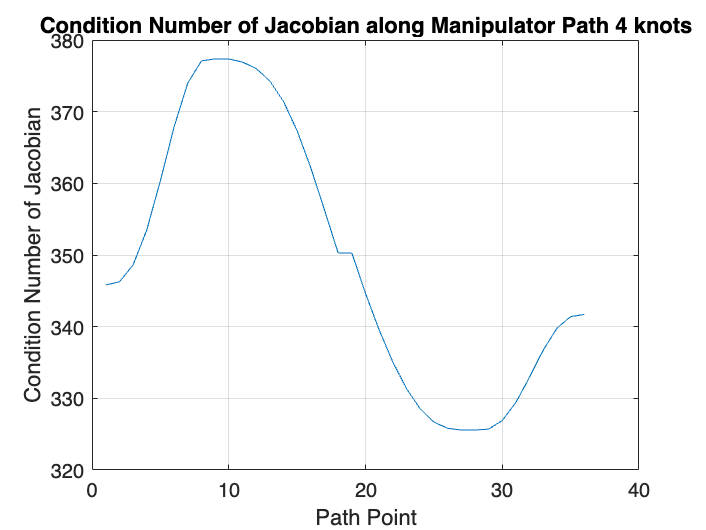



% cond numbers for p6&7
condition_numbers = zeros(size(Q, 1), 1);
for i = 1:length(Q)
    % Get the joint configuration for the current point on the path
    joint_config = Q(:,i);
    
    % Compute the Jacobian at this configuration (replace with your Jacobian function)
    J = jacobianEE(joint_config);
    
    % Calculate the condition number of the Jacobian
    condition_numbers(i) = cond(J);
end


% Plot the condition number along the path

figure;
plot(condition_numbers);
xlabel('Path Point');
ylabel('Condition Number of Jacobian');
title('Condition Number of Jacobian along Manipulator Path 4 knots');
grid on;

% Define all 37 knot points from q0 to q36
q0 = q(1, :);
q1 = q(2, :);
q2 = q(3, :);
q3 = q(4, :);
q4 = q(5, :);
q5 = q(6, :);
q6 = q(7, :);
q7 = q(8, :);
q8 = q(9, :);
q9 = q(10, :);
q10 = q(11, :);
q11 = q(12, :);
q12 = q(13, :);
q13 = q(14, :);
q14 = q(15, :);
q15 = q(16, :);
q16 = q(17, :);
q17 = q(18, :);
q18 = q(19, :);
q19 = q(20, :);
q20 = q(21, :);
q21 = q(22, :);
q22 = q(23, :);
q23 = q(24, :);
q24 = q(25, :);
q25 = q(26, :);
q26 = q(27, :);
q27 = q(28, :);
q28 = q(29, :);
q29 = q(30, :);
q30 = q(31, :);
q31 = q(32, :);
q32 = q(33, :);
q33 = q(34, :);
q34 = q(35, :);
q35 = q(36, :);
q36 = q(37, :);  % Final knot point

% Define all 36 boundary velocities
v0 = [0 0 0]';
v1 = [0 0 0]';
v2 = [0 0 0]';
v3 = [0 0 0]';
v4 = [0 0 0]';
v5 = [0 0 0]';
v6 = [0 0 0]';
v7 = [0 0 0]';
v8 = [0 0 0]';
v9 = [0 -27 0]';
v10 = [0 -27 0]';
v11 = [0 -27 0]';
v12 = [0 -27 0]';
v13 = [0 -27 0]';
v14 = [0 -27 0]';
v15 = [0 -27 0]';
v16 = [0 -27 0]';
v17 = [0 -27 0]';
v18 = [0 0 -27]';
v19 = [0 0 -27]';
v20 = [0 0 -27]';
v21 = [0 0 -27]';
v22 = [0 0 -27]';
v23 = [0 0 -27]';
v24 = [0 0 -27]';
v25 = [0 0 -27]';
v26 = [0 0 -27]';
v27 = [0 27 0]';
v28 = [0 27 0]';
v29 = [0 27 0]';
v30 = [0 27 0]';
v31 = [0 27 0]';
v32 = [0 27 0]';
v33 = [0 27 0]';
v34 = [0 27 0]';
v35 = [0 27 0]';
v36 = [0 0 0]';

% Compute the quintic interpolation coefficients for each of the 36 segments
segments = cell(1, 36);
segments{1} = quintic_interpolationV(0, 0.222, q0, v0, [0 0 0 0]', q1, v1, [0 0 0 0]');
segments{2} = quintic_interpolationV(0, 0.222, q1, v1, [0 0 0 0]', q2, v2, [0 0 0 0]');
segments{3} = quintic_interpolationV(0, 0.222, q2, v2, [0 0 0 0]', q3, v3, [0 0 0 0]');
segments{4} = quintic_interpolationV(0, 0.222, q3, v3, [0 0 0 0]', q4, v4, [0 0 0 0]');
segments{5} = quintic_interpolationV(0, 0.222, q4, v4, [0 0 0 0]', q5, v5, [0 0 0 0]');
segments{6} = quintic_interpolationV(0, 0.222, q5, v5, [0 0 0 0]', q6, v6, [0 0 0 0]');
segments{7} = quintic_interpolationV(0, 0.222, q6, v6, [0 0 0 0]', q7, v7, [0 0 0 0]');
segments{8} = quintic_interpolationV(0, 0.222, q7, v7, [0 0 0 0]', q8, v8, [0 0 0 0]');
segments{9} = quintic_interpolationV(0, 0.222, q8, v8, [0 0 0 0]', q9, v9, [0 0 0 0]');
segments{10} = quintic_interpolationV(0, 0.222, q9, v9, [0 0 0 0]', q10, v10, [0 0 0 0]');
segments{11} = quintic_interpolationV(0, 0.222, q10, v10, [0 0 0 0]', q11, v11, [0 0 0 0]');
segments{12} = quintic_interpolationV(0, 0.222, q11, v11, [0 0 0 0]', q12, v12, [0 0 0 0]');
segments{13} = quintic_interpolationV(0, 0.222, q12, v12, [0 0 0 0]', q13, v13, [0 0 0 0]');
segments{14} = quintic_interpolationV(0, 0.222, q13, v13, [0 0 0 0]', q14, v14, [0 0 0 0]');
segments{15} = quintic_interpolationV(0, 0.222, q14, v14, [0 0 0 0]', q15, v15, [0 0 0 0]');
segments{16} = quintic_interpolationV(0, 0.222, q15, v15, [0 0 0 0]', q16, v16, [0 0 0 0]');
segments{17} = quintic_interpolationV(0, 0.222, q16, v16, [0 0 0 0]', q17, v17, [0 0 0 0]');
segments{18} = quintic_interpolationV(0, 0.222, q17, v17, [0 0 0 0]', q18, v18, [0 0 0 0]');
segments{19} = quintic_interpolationV(0, 0.222, q18, v18, [0 0 0 0]', q19, v19, [0 0 0 0]');
segments{20} = quintic_interpolationV(0, 0.222, q19, v19, [0 0 0 0]', q20, v20, [0 0 0 0]');
segments{21} = quintic_interpolationV(0, 0.222, q20, v20, [0 0 0 0]', q21, v21, [0 0 0 0]');
segments{22} = quintic_interpolationV(0, 0.222, q21, v21, [0 0 0 0]', q22, v22, [0 0 0 0]');
segments{23} = quintic_interpolationV(0, 0.222, q22, v22, [0 0 0 0]', q23, v23, [0 0 0 0]');
segments{24} = quintic_interpolationV(0, 0.222, q23, v23, [0 0 0 0]', q24, v24, [0 0 0 0]');
segments{25} = quintic_interpolationV(0, 0.222, q24, v24, [0 0 0 0]', q25, v25, [0 0 0 0]');
segments{26} = quintic_interpolationV(0, 0.222, q25, v25, [0 0 0 0]', q26, v26, [0 0 0 0]');
segments{27} = quintic_interpolationV(0, 0.222, q26, v26, [0 0 0 0]', q27, v27, [0 0 0 0]');
segments{28} = quintic_interpolationV(0, 0.222, q27, v27, [0 0 0 0]', q28, v28, [0 0 0 0]');
segments{29} = quintic_interpolationV(0, 0.222, q28, v28, [0 0 0 0]', q29, v29, [0 0 0 0]');
segments{30} = quintic_interpolationV(0, 0.222, q29, v29, [0 0 0 0]', q30, v30, [0 0 0 0]');
segments{31} = quintic_interpolationV(0, 0.222, q30, v30, [0 0 0 0]', q31, v31, [0 0 0 0]');
segments{32} = quintic_interpolationV(0, 0.222, q31, v31, [0 0 0 0]', q32, v32, [0 0 0 0]');
segments{33} = quintic_interpolationV(0, 0.222, q32, v32, [0 0 0 0]', q33, v33, [0 0 0 0]');
segments{34} = quintic_interpolationV(0, 0.222, q33, v33, [0 0 0 0]', q34, v34, [0 0 0 0]');
segments{35} = quintic_interpolationV(0, 0.222, q34, v34, [0 0 0 0]', q35, v35, [0 0 0 0]');
segments{36} = quintic_interpolationV(0, 0.222, q35, v35, [0 0 0 0]', q36, v36, [0 0 0 0]');  % Final segment to q36

% Create time vector for interpolation
t = linspace(0, 0.2222, 10);

% Define and evaluate each segment at time points
Q = [];
for idx = 1:length(segments)
    coeffs = segments{idx};
    q1 = coeffs(1,6)*t.^5 + coeffs(1,5)*t.^4 + coeffs(1,4)*t.^3 + coeffs(1,3)*t.^2 + coeffs(1,2)*t + coeffs(1,1);
    q2 = coeffs(2,6)*t.^5 + coeffs(2,5)*t.^4 + coeffs(2,4)*t.^3 + coeffs(2,3)*t.^2 + coeffs(2,2)*t + coeffs(2,1);
    q3 = coeffs(3,6)*t.^5 + coeffs(3,5)*t.^4 + coeffs(3,4)*t.^3 + coeffs(3,3)*t.^2 + coeffs(3,2)*t + coeffs(3,1);
    q4 = coeffs(4,6)*t.^5 + coeffs(4,5)*t.^4 + coeffs(4,4)*t.^3 + coeffs(4,3)*t.^2 + coeffs(4,2)*t + coeffs(4,1);
    
    Q = [Q, [q1; q2; q3; q4]];  % Append to the full trajectory matrix
end

% Forward Kinematics and Plotting
% Initialize pos as a 4x4 matrix with as many columns as Q has
pos = sym(zeros(4, 4, size(Q, 2)));

for i = 1:size(Q, 2)
    theta = Q(:, i);  % Extract each column vector of Q
    pos(:, :, i) = vpa(simplify(subs(A04_simp, [theta1_val, theta2_val, theta3_val, theta4_val], theta')), 3);
end

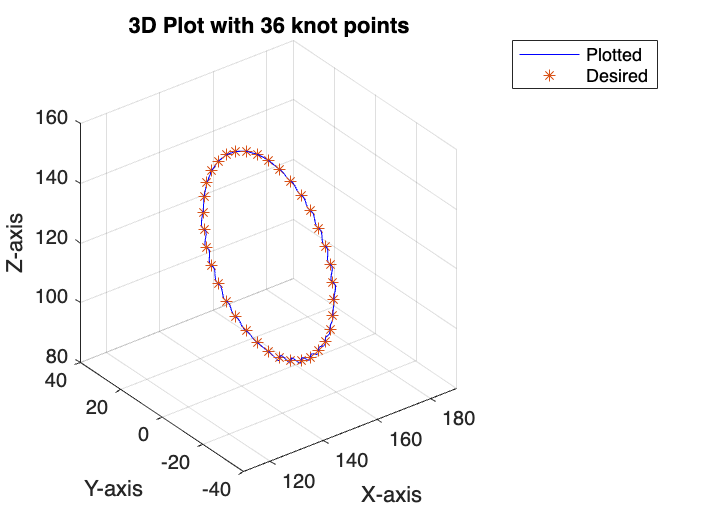


% Extract 3D coordinates
xyz = double(pos(1:3,4,:));
x = squeeze(xyz(1, 1, :));
y = squeeze(xyz(2, 1, :));
z = squeeze(xyz(3, 1, :));

% Plot in 3D
figure;
plot3(x, y, z, 'b');  % 'o' specifies points, you can change to '-' for lines
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('3D Plot with 36 knot points');
hold on
plot3(P(1,:),P(2, :), P(3, :),'*');
grid on;
legend("Plotted","Desired")
xlim([110 190]);  % Set limits for the x-axis
ylim([-40 40]);   % Set limits for the y-axis
zlim([80 160]);    % Set limits for the z-axis

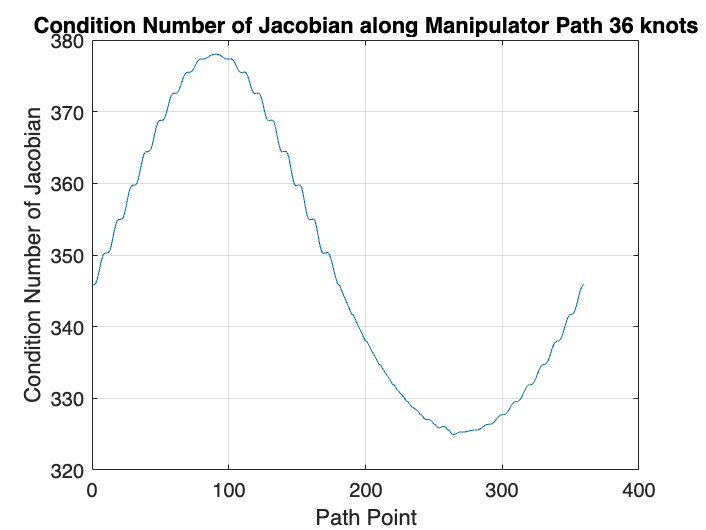

% cond numbers for p6&7
condition_numbers = zeros(size(Q, 1), 1);
for i = 1:length(Q)
    % Get the joint configuration for the current point on the path
    joint_config = Q(:,i);
    
    % Compute the Jacobian at this configuration (replace with your Jacobian function)
    J = jacobianEE(joint_config);
    
    % Calculate the condition number of the Jacobian
    condition_numbers(i) = cond(J);
end


% Plot the condition number along the path
figure;
plot(condition_numbers);
xlabel('Path Point');
ylabel('Condition Number of Jacobian');
title('Condition Number of Jacobian along Manipulator Path 36 knots');
grid on;



% % cond numbers for p6&7
% condition_numbers = zeros(size(QQ, 1), 1);
% for i = 1:length(QQ)
%     % Get the joint configuration for the current point on the path
%     joint_config = QQ(:,i);
% 
%     % Compute the Jacobian at this configuration (replace with your Jacobian function)
%     J = jacobianEE(joint_config);
% 
%     % Calculate the condition number of the Jacobian
%     condition_numbers(i) = cond(J);
% end


% Plot the condition number along the path
% figure;
% plot(condition_numbers);
% xlabel('Path Point');
% ylabel('Condition Number of Jacobian');
% title('Condition Number of Jacobian along Manipulator Path');
% grid on;

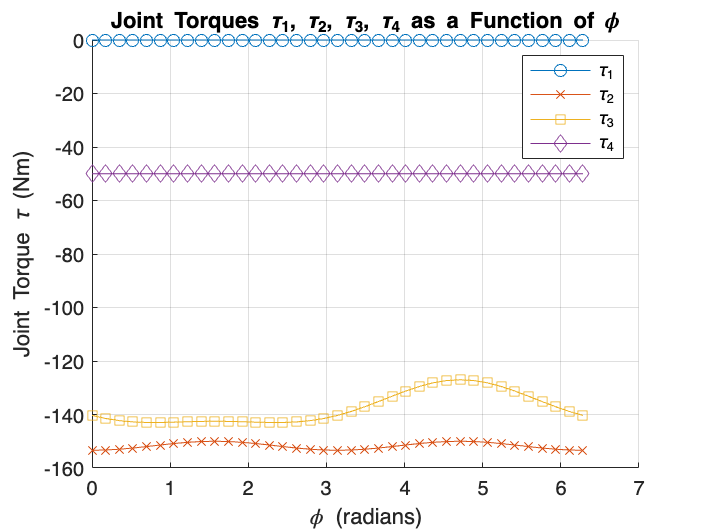

% Calculate and plot all joint torques τ1, τ2, τ3, τ4 as a function of φ

% Force applied in the negative Z direction
F = [0 0 -1 0 0 0]'; % 1N of force

% Compute Jacobians and torques
J_all = cell(1, length(phi));
tau = zeros(length(phi), 4); % Preallocate tau with the same number of columns as q

for i = 1:length(phi)
    J_all{i} = jacobianEE(q(i, :)); % Store each Jacobian in a cell array
    tau(i, :) = (J_all{i}' * F)'; % Calculate tau and store as a row in tau
end

% Plot each joint torque as a function of phi
figure;
hold on;
plot(phi, tau(:, 1), '-o', 'DisplayName', '\tau_1');
plot(phi, tau(:, 2), '-x', 'DisplayName', '\tau_2');
plot(phi, tau(:, 3), '-s', 'DisplayName', '\tau_3');
plot(phi, tau(:, 4), '-d', 'DisplayName', '\tau_4');

xlabel('\phi (radians)');
ylabel('Joint Torque \tau (Nm)');
title('Joint Torques \tau_1, \tau_2, \tau_3, \tau_4 as a Function of \phi');
legend;
grid on;
hold off;

Rcm1 = A1_evaluated(1:3,1:3);
Ocm1 = A1_evaluated(1:3,4) - [0 0 20]';
Hcm1 = [Rcm1 Ocm1;
    0 0 0 1]

$$Hcm1 = \left(\begin{array}{cccc} \cos\left(\theta_{1,\mathrm{val}}\right) & 0 & \sin\left(\theta_{1,\mathrm{val}}\right) & 0\\ \sin\left(\theta_{1,\mathrm{val}}\right) & 0 & -\cos\left(\theta_{1,\mathrm{val}}\right) & 0\\ 0 & 1 & 0 & 30\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H01 = A1_evaluated

$$H01 = \left(\begin{array}{cccc} \cos\left(\theta_{1,\mathrm{val}}\right) & 0 & \sin\left(\theta_{1,\mathrm{val}}\right) & 0\\ \sin\left(\theta_{1,\mathrm{val}}\right) & 0 & -\cos\left(\theta_{1,\mathrm{val}}\right) & 0\\ 0 & 1 & 0 & 50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

O1 = H01(1:3,4);

H02 =(A1_evaluated*A2_evaluated)

$$H02 = \left(\begin{array}{cccc} \cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right) & -\cos\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{2,\mathrm{val}}\right) & \sin\left(\theta_{1,\mathrm{val}}\right) & 93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right)\\ \cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\sin\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{2,\mathrm{val}}\right) & -\cos\left(\theta_{1,\mathrm{val}}\right) & 93\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\\ \sin\left(\theta_{2,\mathrm{val}}\right) & \cos\left(\theta_{2,\mathrm{val}}\right) & 0 & 93\,\sin\left(\theta_{2,\mathrm{val}}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

O2 = H02(1:3,4);
Rcm2 = H02(1:3,1:3);
Ocm2 = H02(1:3,4)-[0 0 30]';
Hcm2 = [Rcm2 Ocm2;
    0 0 0 1]

$$Hcm2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right) & -\cos\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{2,\mathrm{val}}\right) & \sin\left(\theta_{1,\mathrm{val}}\right) & 93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right)\\ \cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\sin\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{2,\mathrm{val}}\right) & -\cos\left(\theta_{1,\mathrm{val}}\right) & 93\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\\ \sin\left(\theta_{2,\mathrm{val}}\right) & \cos\left(\theta_{2,\mathrm{val}}\right) & 0 & 93\,\sin\left(\theta_{2,\mathrm{val}}\right)+20\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H03 = simplify(A1_evaluated*A2_evaluated*A3_evaluated)

$$H03 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\cos\left(\theta_{1,\mathrm{val}}\right) & -\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\cos\left(\theta_{1,\mathrm{val}}\right) & \sin\left(\theta_{1,\mathrm{val}}\right) & 93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{1}\\ \cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\cos\left(\theta_{1,\mathrm{val}}\right) & 93\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{1}\\ \sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right) & \cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right) & 0 & 93\,\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+93\,\sin\left(\theta_{2,\mathrm{val}}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+\cos\left(\theta_{2,\mathrm{val}}\right) \end{array}$$

O3 = H03(1:3,4);
Rcm3 = H03(1:3,1:3);
Ocm3 = H03(1:3,4)-[0 0 30]';
Hcm3 = [Rcm3 Ocm3;
    0 0 0 1]

$$Hcm3 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\cos\left(\theta_{1,\mathrm{val}}\right) & -\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\cos\left(\theta_{1,\mathrm{val}}\right) & \sin\left(\theta_{1,\mathrm{val}}\right) & 93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{1}\\ \cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right) & -\cos\left(\theta_{1,\mathrm{val}}\right) & 93\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{1}\\ \sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right) & \cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right) & 0 & 93\,\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+93\,\sin\left(\theta_{2,\mathrm{val}}\right)+20\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+\cos\left(\theta_{2,\mathrm{val}}\right) \end{array}$$



H04 = A4_evaluated

$$H04 = \left(\begin{array}{cccc} \cos\left(\theta_{4,\mathrm{val}}\right) & -\sin\left(\theta_{4,\mathrm{val}}\right) & 0 & 50\,\cos\left(\theta_{4,\mathrm{val}}\right)\\ \sin\left(\theta_{4,\mathrm{val}}\right) & \cos\left(\theta_{4,\mathrm{val}}\right) & 0 & 50\,\sin\left(\theta_{4,\mathrm{val}}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

O4 = H04(1:3,4);
Rcm4 = H04(1:3,1:3);
Ocm4 = H04(1:3,4)-[15 0 25]';
Hcm4 = [Rcm4 Ocm4;
    0 0 0 1]

$$Hcm4 = \left(\begin{array}{cccc} \cos\left(\theta_{4,\mathrm{val}}\right) & -\sin\left(\theta_{4,\mathrm{val}}\right) & 0 & 50\,\cos\left(\theta_{4,\mathrm{val}}\right)-15\\ \sin\left(\theta_{4,\mathrm{val}}\right) & \cos\left(\theta_{4,\mathrm{val}}\right) & 0 & 50\,\sin\left(\theta_{4,\mathrm{val}}\right)\\ 0 & 0 & 1 & -25\\ 0 & 0 & 0 & 1 \end{array}\right)$$



% Reiknum Jacobian fyrir CM1
Z0 = [0 0 1]';
Z1 = Z0;
Z2 = Z1;
Z3 = Z1;
Z4 = Z1;

O0 = [0 0 0]';


Jc1 = [cross(Z0,(Ocm1-O0));
    Z0];

Jc1 = [Jc1 [0;0;0;0;0;0]]

$$Jc1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$



Jc2 = [cross(Z0,(Ocm2-O0)) cross(Z1,(Ocm2-O1));
    Z0 Z1]

$$Jc2 = \left(\begin{array}{cc} -93\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right) & -93\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\\ 93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right) & 93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right)\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$


Jc3 = [cross(Z0,(Ocm3-O0)) cross(Z1,(Ocm3-O1)) cross(Z2,(Ocm3-O2));
    Z0 Z1 Z2]

$$Jc3 = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{2} & -\sigma_{2} & 93\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)+\left(-\sigma_{2}\right)\\ \sigma_{1} & \sigma_{1} & \sigma_{1}-93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right)\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\left(\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+\cos\left(\theta_{2,\mathrm{val}}\right)\right)\\ \sigma_{2}=93\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\left(\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+\cos\left(\theta_{2,\mathrm{val}}\right)\right) \end{array}$$


Jc4 = [cross(Z0,(Ocm4-O0)) cross(Z1,(Ocm4-O1)) cross(Z2,(Ocm4-O2)) cross(Z3,(Ocm4-O3));
    Z0 Z1 Z2 Z3]

$$Jc4 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3} & \sigma_{3} & 93\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)+\sigma_{3} & 93\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{1}+\sigma_{3}\\ \sigma_{2} & \sigma_{2} & 50\,\cos\left(\theta_{4,\mathrm{val}}\right)-93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right)-15 & 50\,\cos\left(\theta_{4,\mathrm{val}}\right)-93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{1}-15\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+\cos\left(\theta_{2,\mathrm{val}}\right)\\ \sigma_{2}=50\,\cos\left(\theta_{4,\mathrm{val}}\right)-15\\ \sigma_{3}=-50\,\sin\left(\theta_{4,\mathrm{val}}\right) \end{array}$$


J_vc1 = Jc1(1:3,:)

$$J\_vc1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

J_w1 = Jc1(4:6,:)

$$J\_w1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$


J_vc2 = Jc2(1:3,:)

$$J\_vc2 = \left(\begin{array}{cc} -93\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right) & -93\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\\ 93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right) & 93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right)\\ 0 & 0 \end{array}\right)$$

J_w2 = Jc2(4:6,:)

$$J\_w2 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$


J_vc3 = Jc3(1:3,:)

$$J\_vc3 = \begin{array}{l} \left(\begin{array}{ccc} -93\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\left(\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+\cos\left(\theta_{2,\mathrm{val}}\right)\right) & -93\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\left(\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+\cos\left(\theta_{2,\mathrm{val}}\right)\right) & 93\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)-93\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\left(\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+\cos\left(\theta_{2,\mathrm{val}}\right)\right)\\ \sigma_{1} & \sigma_{1} & \sigma_{1}-93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right)\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\left(\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+\cos\left(\theta_{2,\mathrm{val}}\right)\right) \end{array}$$

J_w3 = Jc3(4:6,:)

$$J\_w3 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 1 \end{array}\right)$$


J_vc4 = Jc4(1:3,:)

$$J\_vc4 = \begin{array}{l} \left(\begin{array}{cccc} -50\,\sin\left(\theta_{4,\mathrm{val}}\right) & -50\,\sin\left(\theta_{4,\mathrm{val}}\right) & 93\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)-50\,\sin\left(\theta_{4,\mathrm{val}}\right) & 93\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{1}-50\,\sin\left(\theta_{4,\mathrm{val}}\right)\\ \sigma_{2} & \sigma_{2} & 50\,\cos\left(\theta_{4,\mathrm{val}}\right)-93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right)-15 & 50\,\cos\left(\theta_{4,\mathrm{val}}\right)-93\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{1}-15\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)+\cos\left(\theta_{2,\mathrm{val}}\right)\\ \sigma_{2}=50\,\cos\left(\theta_{4,\mathrm{val}}\right)-15 \end{array}$$

J_w4 = Jc4(4:6,:)

$$J\_w4 = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)$$

% Dynamics 

% Finnum homogenius transform yfir í CM1,2,3 og 4


% link 1
a = 50*10^(-3); %m
b = 50*10^(-3);
m = 0.06 %kg

m = 0.0600


I0 = (m*(a^2 + b^2))/(12);

D1 = [I0 0 0;0 0.4*I0 0;0 0 0.9*I0]

D1 = 1.0e-04 *

    0.2500         0         0
         0    0.1000         0
         0         0    0.2250


D2 = [0.45*I0 0 0; 0 1.45*I0 0;0 0 1.2*I0]

D2 = 1.0e-04 *

    0.1125         0         0
         0    0.3625         0
         0         0    0.3000


D3 = D2;
D4 = [0.5*I0 0 0; 0 0.5*I0 0; 0 0 0.5*I0]

D4 = 1.0e-04 *

    0.1250         0         0
         0    0.1250         0
         0         0    0.1250




J1 = vpa(Rcm1*D1*(Rcm1.'))

$$J1 = \left(\begin{array}{ccc} 0.000025\,{\cos\left(\theta_{1,\mathrm{val}}\right)}^{2}+0.000022500000000000001417052239438554\,{\sin\left(\theta_{1,\mathrm{val}}\right)}^{2} & 0.0000024999999999999985829477605614457\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right) & 0\\ 0.0000024999999999999985829477605614457\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right) & 0.000022500000000000001417052239438554\,{\cos\left(\theta_{1,\mathrm{val}}\right)}^{2}+0.000025\,{\sin\left(\theta_{1,\mathrm{val}}\right)}^{2} & 0\\ 0 & 0 & 0.00001 \end{array}\right)$$

J2 = vpa(Rcm2*D2*(Rcm2.'))

$$J2 = \begin{array}{l} \left(\begin{array}{ccc} 0.000011250000000000000708526119719277\,{\cos\left(\theta_{1,\mathrm{val}}\right)}^{2}\,{\cos\left(\theta_{2,\mathrm{val}}\right)}^{2}+0.000036250000000000000212503625807159\,{\cos\left(\theta_{1,\mathrm{val}}\right)}^{2}\,{\sin\left(\theta_{2,\mathrm{val}}\right)}^{2}+0.00003\,{\sin\left(\theta_{1,\mathrm{val}}\right)}^{2} & \sigma_{1} & \sigma_{3}\\ \sigma_{1} & 0.00003\,{\cos\left(\theta_{1,\mathrm{val}}\right)}^{2}+0.000011250000000000000708526119719277\,{\cos\left(\theta_{2,\mathrm{val}}\right)}^{2}\,{\sin\left(\theta_{1,\mathrm{val}}\right)}^{2}+0.000036250000000000000212503625807159\,{\sin\left(\theta_{1,\mathrm{val}}\right)}^{2}\,{\sin\left(\theta_{2,\mathrm{val}}\right)}^{2} & \sigma_{2}\\ \sigma_{3} & \sigma_{2} & 0.000036250000000000000212503625807159\,{\cos\left(\theta_{2,\mathrm{val}}\right)}^{2}+0.000011250000000000000708526119719277\,{\sin\left(\theta_{2,\mathrm{val}}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.000011250000000000000708526119719277\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\,{\cos\left(\theta_{2,\mathrm{val}}\right)}^{2}+0.000036250000000000000212503625807159\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\,{\sin\left(\theta_{2,\mathrm{val}}\right)}^{2}-0.00003\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\\ \sigma_{2}=-0.000024999999999999999503977506087882\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{2,\mathrm{val}}\right)\\ \sigma_{3}=-0.000024999999999999999503977506087882\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\cos\left(\theta_{2,\mathrm{val}}\right)\,\sin\left(\theta_{2,\mathrm{val}}\right) \end{array}$$

J3 = vpa(Rcm3*D3*(Rcm3.'))

$$J3 = \begin{array}{l} \left(\begin{array}{ccc} 0.000011250000000000000708526119719277\,\sigma_{5}\,{\cos\left(\theta_{1,\mathrm{val}}\right)}^{2}+0.000036250000000000000212503625807159\,\sigma_{4}\,{\cos\left(\theta_{1,\mathrm{val}}\right)}^{2}+0.00003\,{\sin\left(\theta_{1,\mathrm{val}}\right)}^{2} & \sigma_{3} & \sigma_{2}\\ \sigma_{3} & 0.000011250000000000000708526119719277\,\sigma_{5}\,{\sin\left(\theta_{1,\mathrm{val}}\right)}^{2}+0.000036250000000000000212503625807159\,\sigma_{4}\,{\sin\left(\theta_{1,\mathrm{val}}\right)}^{2}+0.00003\,{\cos\left(\theta_{1,\mathrm{val}}\right)}^{2} & \sigma_{1}\\ \sigma_{2} & \sigma_{1} & 0.000036250000000000000212503625807159\,\sigma_{5}+0.000011250000000000000708526119719277\,\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-0.000024999999999999999503977506087882\,\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\\ \sigma_{2}=-0.000024999999999999999503977506087882\,\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)\,\cos\left(\theta_{1,\mathrm{val}}\right)\\ \sigma_{3}=0.000011250000000000000708526119719277\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{5}+0.000036250000000000000212503625807159\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\,\sigma_{4}-0.00003\,\cos\left(\theta_{1,\mathrm{val}}\right)\,\sin\left(\theta_{1,\mathrm{val}}\right)\\ \sigma_{4}={\sin\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)}^{2}\\ \sigma_{5}={\cos\left(\theta_{2,\mathrm{val}}+\theta_{3,\mathrm{val}}\right)}^{2} \end{array}$$

J4 = vpa(Rcm4*D4*(Rcm4.'))

$$J4 = \left(\begin{array}{ccc} 0.0000125\,{\cos\left(\theta_{4,\mathrm{val}}\right)}^{2}+0.0000125\,{\sin\left(\theta_{4,\mathrm{val}}\right)}^{2} & 0 & 0\\ 0 & 0.0000125\,{\cos\left(\theta_{4,\mathrm{val}}\right)}^{2}+0.0000125\,{\sin\left(\theta_{4,\mathrm{val}}\right)}^{2} & 0\\ 0 & 0 & 0.0000125 \end{array}\right)$$


%D = ((m*(J_vc1.')*J_vc1)+(J_w1.'*J1*J_w1)) + ((m*(J_vc2.')*J_vc2)+(J_w2.'*J2*J_w2)) +((m*(J_vc3.')*J_vc3)+(J_w3.'*3*J_w3)) + ((m*(J_vc4.')*J_vc4)+(J_w4.'*J4*J_w4))



